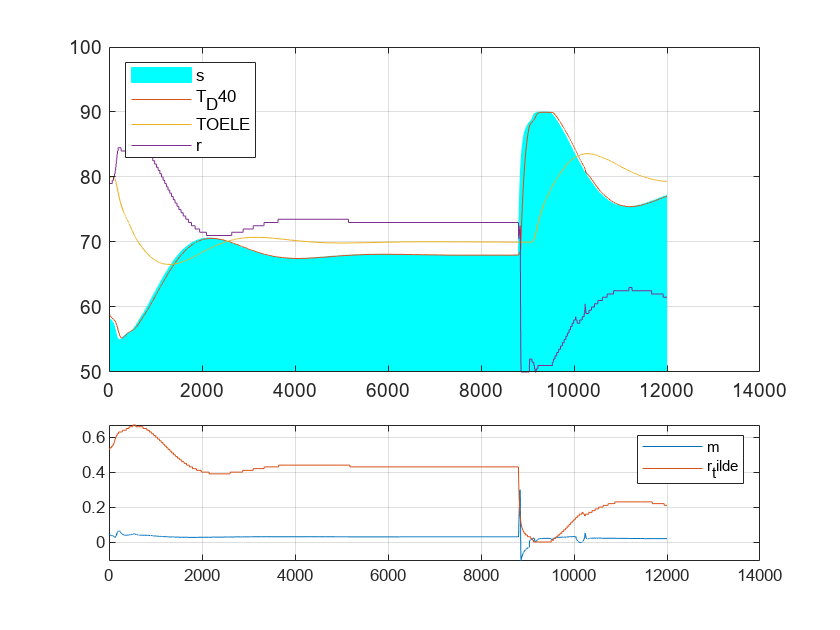

clear
eins = [1; 2; 3; 4];
zwei = 2 * eins;
drei = 3 * eins;
t = table(eins, zwei, drei);
writetable(t, 'tabellentest.txt');

while true
    try
        p = readtable("Raspberry pi git\ABB_pi\Monitor/log.txt");
    catch exception
    end
    l = size(p); l=l(1);
    start = max(1,l-12000);
    p = p(start:end,:);
    
    subplot(3,1,[1 2])
    
    area(p.s_V,'FaceColor','c','EdgeColor','c')
    hold on
    plot(p.T_D40)
    plot(p.TOELE)
    grid on
    plot(50 + p.r * 50)
    hold off
    legend({ 's','T_D40', 'TOELE', 'r'}, 'Location', 'northwest');
    ylim([50 100])
    subplot(3,1,3)
    plot(p.m)
    hold on
    plot(p.r_tilde)
    legend({'m','r_tilde'})
    %text(0.1,0.1,sprintf('s_V = %.2f', p.s_V(end)))
    grid on
    hold off
    drawnow

    pause(1)
end